# Induction Machine Simulation

clc
clear all
close all
rng(0)

# Parameters

## Simulation

Tf = 4;        % Total simulation time
fs = 6e3;
Ts = 1/fs        % Sampling time

Ts = 1.6667e-04

Ns = ceil(Tf/Ts) % Number of sampling steps

Ns = 24000

Ni = 40;         % Number of integration steps between each ISR (Interrupt Service Routine)
Ti = Ts/Ni	     % Integration step

Ti = 4.1667e-06

## Machine parameters

specsIM = struct();

specsIM.Ti = Ti;

IM = ClassIM(specsIM)

IM =   ClassIM with properties:

         Ti: 4.1667e-06
       VLLN: 380
         fN: 50
         PN: 3000
        FPn: 0.8100
         SN: 3.7037e+03
         wN: 151.8436
         IN: 5.6272
         np: 2
          J: 0.0060
         TN: 19.7572
         Rs: 1.8000
         Rr: 1.8000
        Los: 0.0026
        Lor: 0.0026
         Lm: 0.2351
         Ls: 0.2377
         Lr: 0.2377
         kr: 0.9891
         ks: 0.9891
      tau_r: 0.1321
      sigma: 0.0218
       Rsig: 3.5608
        FrN: 0.9876
       isdN: 4.2008
         kT: 2.9672
          R: [6×6 double]
        Lss: [3×3 double]
        Lrr: [3×3 double]
       pi23: 2.0944
        Lsr: @(g)obj.Lm*cos(g+obj.pi23*[0,1,-1;-1,0,1;1,-1,0])
    dLsr_dt: @(g,w)obj.np*w*obj.dLsr_dg(g)
    dLsr_dg: @(g)-obj.Lm*sin(g+obj.pi23*[0,1,-1;-1,0,1;1,-1,0])
          L: @(g)[obj.Lss,obj.Lsr(g);obj.Lsr(g)',obj.Lrr]
         dL: @(g,w)[zeros(3),obj.dLsr_dt(g,w);obj.dLsr_dt

RFT = reference_frame_transforms();

i_dq_vec = zeros(4, Ns);
F_dq_vec = zeros(4, Ns);
vs_dq_vec = zeros(2, Ns);

i_abc_vec = zeros(6, Ns);
F_abc_vec = zeros(6, Ns);
vs_abc_vec = zeros(3, Ns);

w_vec = zeros(1, Ns);
Te_vec = zeros(1, Ns);

ws_vec = 2*pi*30 * ones(Ns, 1);
vs_vec = sqrt(2/3)*IM.VLLN * ones(Ns, 1) *30/50;

ws_vec(1:floor(Ns/2)) = 2*pi*30 * linspace(0, 1, floor(Ns/2));
vs_vec(1:floor(Ns/2)) = sqrt(2)*IM.VLLN/sqrt(3) * linspace(0, 1, floor(Ns/2)) *30/50;

i = zeros(6, 1);
w = 0;
gs = 0;

for ts = 1:Ns

ws = ws_vec(ts);
vs = vs_vec(ts) * cos(gs + [0; -IM.pi23; IM.pi23]);

for ti = 1:Ni
    IM = IM.step(vs);
end

i_dq_vec(:, ts) = [RFT.abc2dq(IM.g) * IM.i(1:3); RFT.abc2dq(IM.g) * IM.i(4:6)];
F_dq_vec(:, ts) = [RFT.abc2dq(IM.g) * IM.F(1:3); RFT.abc2dq(IM.g) * IM.F(4:6)];
vs_dq_vec(:, ts) = RFT.abc2dq(IM.g) * vs;

i_abc_vec(:, ts) = IM.i;
F_abc_vec(:, ts) = IM.F;
vs_abc_vec(:, ts) = vs;

w_vec(ts) = IM.w;
Te_vec(ts) = IM.Te;

gs = gs + ws * Ts;
end

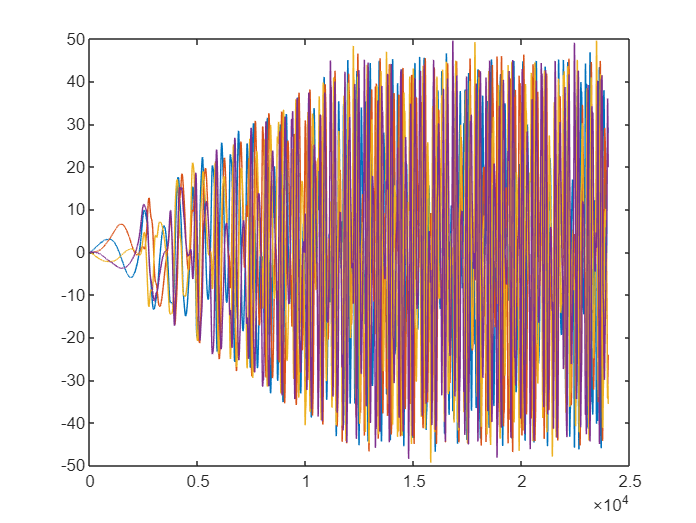

figure
plot(i_dq_vec')

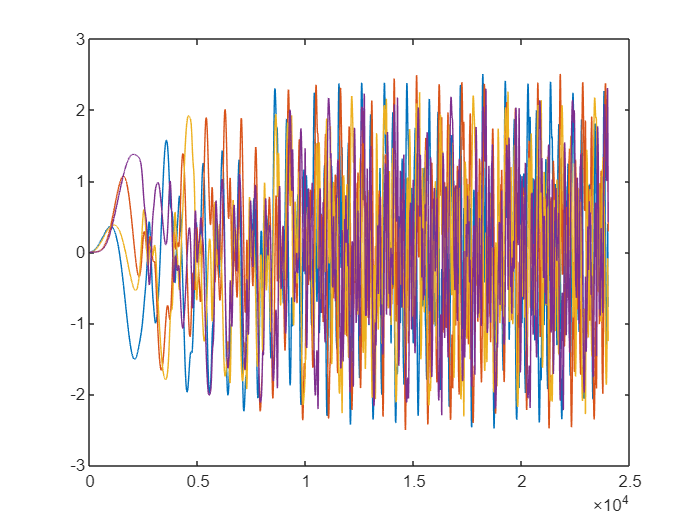


figure
plot(F_dq_vec')

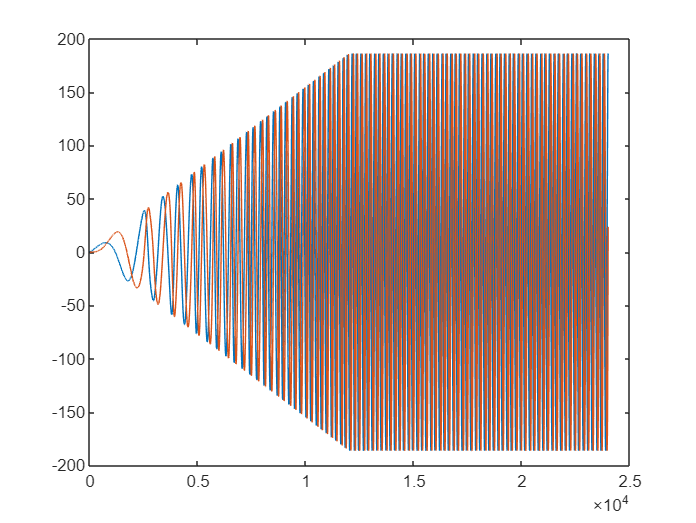


figure
plot(vs_dq_vec')

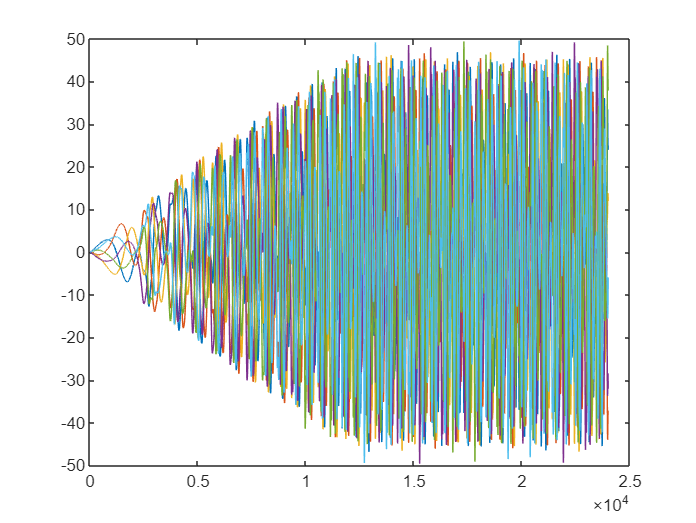


figure
plot(i_abc_vec')

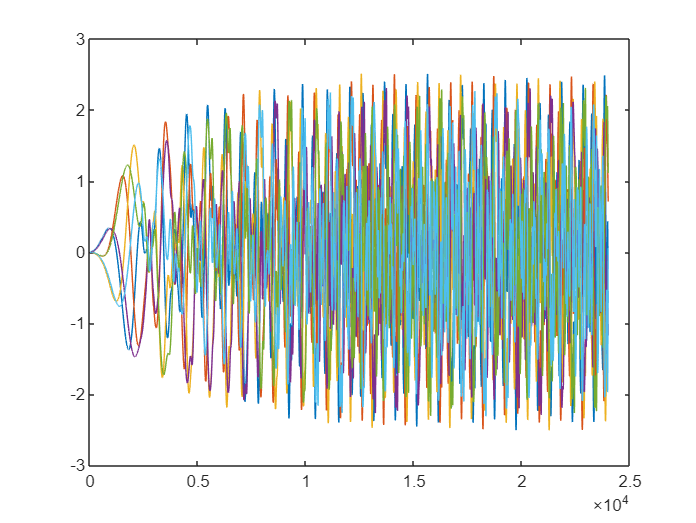


figure
plot(F_abc_vec')

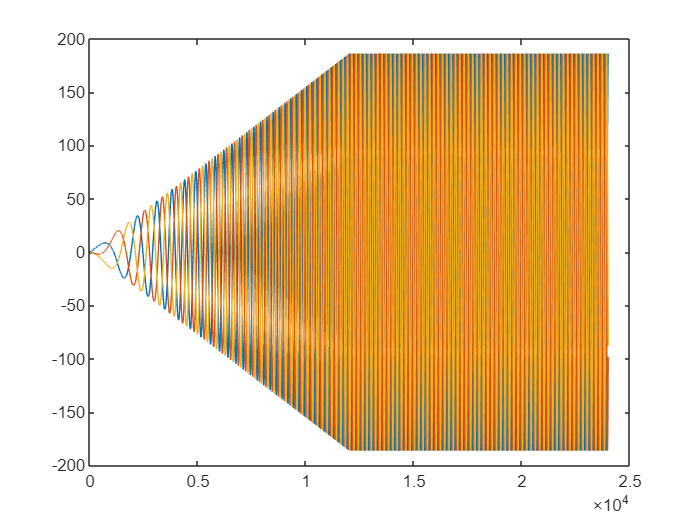


figure
plot(vs_abc_vec')

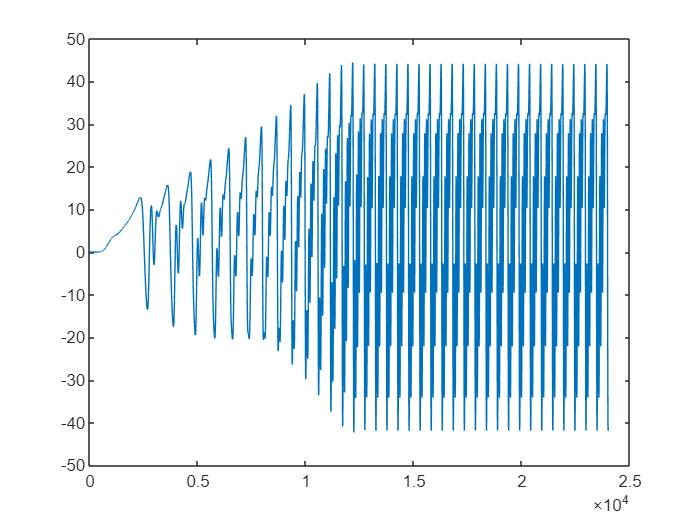


figure
plot(w_vec')

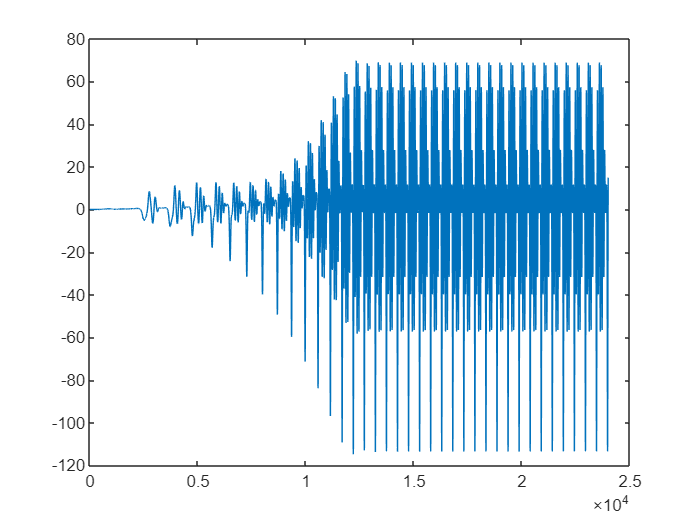


figure
plot(Te_vec')